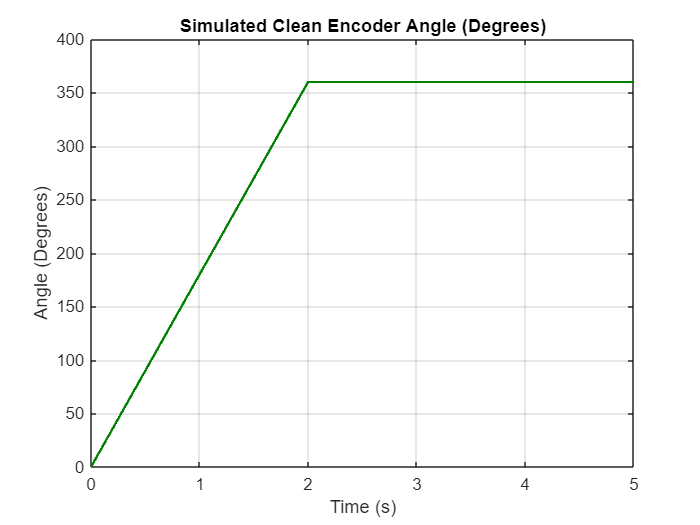

%%Initial Setup and Clean Signal Generation
clear;
clc;
close all;
Fs = 1000;
T = 1/Fs;
L = 5000;
t = (0:L-1)*T;

max_angle_deg = 360;
rotation_time_s = 2;

clean_angle = zeros(1, L);

for i = 1:L
    if t(i) <= rotation_time_s
        
        clean_angle(i) = (t(i) / rotation_time_s) * max_angle_deg;
    else
        
        clean_angle(i) = max_angle_deg;
    end
end

% Plot the clean signal to visualize it.
figure('Name', 'Clean Encoder Signal');
plot(t, clean_angle, 'LineWidth', 1.5, 'Color', [0 0.5 0]); %
title('Simulated Clean Encoder Angle (Degrees)');
xlabel('Time (s)'); % Label x-axis
ylabel('Angle (Degrees)'); % Label y-axis
grid on;

## Phase 2: Adding Noise to the Signal

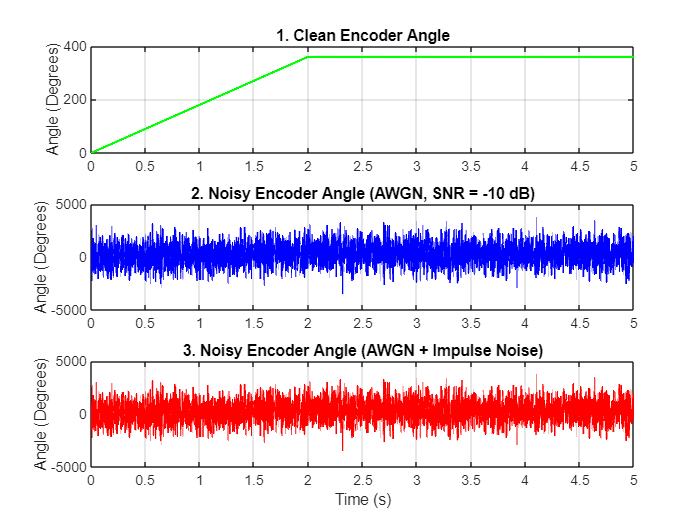

noise_snr_db = -10;
noisy_angle_awgn = awgn(clean_angle, noise_snr_db, 'measured');

% --- Add Impulse Noise (Spikes)---
impulse_percentage = 0.005;
impulse_amplitude = 500;
num_impulses = round(impulse_percentage * L);
impulse_indices = randperm(L, num_impulses);

impulse_noise = zeros(1, L); % Initialize an array of zeros for impulse noise
for i = 1:num_impulses
    % Randomly make spikes positive or negative
    if rand() > 0.5
        impulse_noise(impulse_indices(i)) = impulse_amplitude;
    else
        impulse_noise(impulse_indices(i)) = -impulse_amplitude;
    end
end

% Combine AWGN and Impulse Noise for a more realistic noisy signal.
noisy_angle_combined = noisy_angle_awgn + impulse_noise;

% Plot the noisy signals to compare them with the clean signal.
figure('Name', 'Noisy Encoder Signals');
subplot(3,1,1); % Create a 3-row, 1-column subplot layout, and activate the 1st subplot
plot(t, clean_angle, 'g', 'LineWidth', 1.5);
title('1. Clean Encoder Angle');
ylabel('Angle (Degrees)');
grid on;

subplot(3,1,2); % Activate the 2nd subplot
plot(t, noisy_angle_awgn, 'b', 'LineWidth', 1);
title(['2. Noisy Encoder Angle (AWGN, SNR = ', num2str(noise_snr_db), ' dB)']);
ylabel('Angle (Degrees)');
grid on;

subplot(3,1,3); % Activate the 3rd subplot
plot(t, noisy_angle_combined, 'r', 'LineWidth', 1);
title('3. Noisy Encoder Angle (AWGN + Impulse Noise)');
xlabel('Time (s)');
ylabel('Angle (Degrees)');
grid on;

## Phase 3: Designing and Implementing Digital Filters

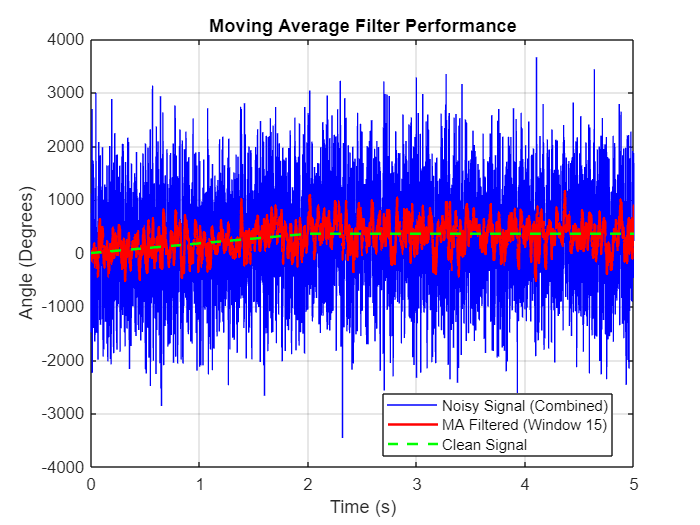

window_size_ma = 15;

b_ma = ones(1, window_size_ma) / window_size_ma; % Numerator coefficients for the filter (all ones, scaled to sum to 1)
a_ma = 1; % Denominator coefficient (always 1 for an FIR filter)

% Apply the MA filter using the 'filter' function
filtered_ma = filter(b_ma, a_ma, noisy_angle_combined);

% Plot MA filter performance
figure('Name', 'Moving Average Filter Performance');
plot(t, noisy_angle_combined, 'b', 'DisplayName', 'Noisy Signal (Combined)');
hold on; % Keep the current plot and add new plots on top
plot(t, filtered_ma, 'r', 'DisplayName', ['MA Filtered (Window ', num2str(window_size_ma), ')'], 'LineWidth', 1.5);
plot(t, clean_angle, 'g--', 'DisplayName', 'Clean Signal', 'LineWidth', 1.5);
title('Moving Average Filter Performance');
xlabel('Time (s)');
ylabel('Angle (Degrees)');
legend('show', 'Location', 'best'); % Show legend, place it optimally
grid on;
hold off; % Release the hold on the plot so future plots don't overwrite this one

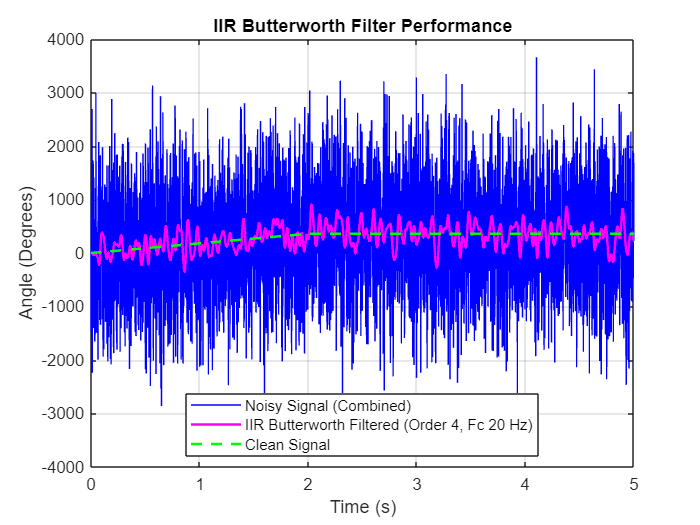




filter_order_iir = 4;
cutoff_freq_hz = 20;
normalized_cutoff_freq = cutoff_freq_hz / (Fs/2);
[b_iir, a_iir] = butter(filter_order_iir, normalized_cutoff_freq, 'low');

% Apply the IIR filter using the 'filter' function
filtered_iir = filter(b_iir, a_iir, noisy_angle_combined);

% Plot IIR filter performance
figure('Name', 'IIR Butterworth Filter Performance');
plot(t, noisy_angle_combined, 'b', 'DisplayName', 'Noisy Signal (Combined)');
hold on;
plot(t, filtered_iir, 'm', 'DisplayName', ['IIR Butterworth Filtered (Order ', num2str(filter_order_iir), ', Fc ', num2str(cutoff_freq_hz), ' Hz)'], 'LineWidth', 1.5);
plot(t, clean_angle, 'g--', 'DisplayName', 'Clean Signal', 'LineWidth', 1.5);
title('IIR Butterworth Filter Performance');
xlabel('Time (s)');
ylabel('Angle (Degrees)');
legend('show', 'Location', 'best');
grid on;
hold off;

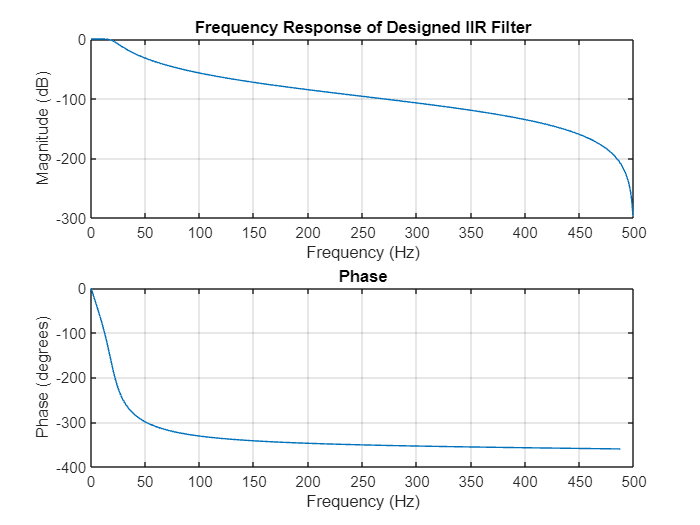



figure('Name', 'IIR Filter Frequency Response');
freqz(b_iir, a_iir, 512, Fs); % Plot magnitude and phase response (512 points, Fs sampling frequency)
title('Frequency Response of Designed IIR Filter');

## Phase 4: Evaluating Filter Performance and Conceptualizing Embedded Implementation

% --- 4.1: Quantitative Performance Metrics ---

% Mean Squared Error (MSE): Measures the average squared difference between
mse_noisy = mean((noisy_angle_combined - clean_angle).^2);
mse_ma = mean((filtered_ma - clean_angle).^2);
mse_iir = mean((filtered_iir - clean_angle).^2);

% Signal-to-Noise Ratio (SNR) in dB
snr_noisy_db = snr(clean_angle, noisy_angle_combined - clean_angle);
snr_ma_db = snr(clean_angle, filtered_ma - clean_angle);
snr_iir_db = snr(clean_angle, filtered_iir - clean_angle);

% Display results in the MATLAB Command Window
fprintf('\n--- Filter Performance Metrics ---\n');


--- Filter Performance Metrics ---


fprintf('Mean Squared Error (MSE):\n');

Mean Squared Error (MSE):


fprintf('  Noisy Signal:        %.2f\n', mse_noisy);

  Noisy Signal:        950781.59


fprintf('  MA Filtered Signal:  %.2f\n', mse_ma);

  MA Filtered Signal:  64517.30


fprintf('  IIR Filtered Signal: %.2f\n', mse_iir);

  IIR Filtered Signal: 39389.89


fprintf('\nSignal-to-Noise Ratio (SNR):\n');


Signal-to-Noise Ratio (SNR):


fprintf('  Noisy Signal:        %.2f dB\n', snr_noisy_db);

  Noisy Signal:        -10.00 dB


fprintf('  MA Filtered Signal:  %.2f dB\n', snr_ma_db);

  MA Filtered Signal:  1.68 dB


fprintf('  IIR Filtered Signal: %.2f dB\n', snr_iir_db);

  IIR Filtered Signal: 3.82 dB



% --- 4.2: Conceptualizing Robustness ---
% "Robustness" means the filter performs well even when noise conditions (type, amplitude) change,
% or when the input signal's characteristics change (e.g., faster rotation, step changes).
% To demonstrate this for your internship, you would:
% 1. Go back to Phase 2 (Step 6) and modify 'noise_snr_db' (e.g., to -5 or -20)
%    or 'impulse_percentage' (e.g., to 0.01 or 0.001).
% 2. Re-run the entire script (F5) and observe how the plots and performance metrics change.
% 3. Discuss which filter parameters (MA window size, IIR order/cutoff) offer the best
%    trade-off between noise reduction and preserving the original signal,
%    and how they hold up under different noise scenarios.

% --- 4.3: Conceptual C-Code for Embedded Implementation ---
% This section shows how a filter (specifically MA) would be implemented on a microcontroller
% (e.g., in a real AS5147U encoder application). This code is for understanding and discussion,
% not for execution in MATLAB. It directly addresses the 'C' and 'Coding' skills.

%{
// C-Code Snippet for Moving Average Filter (Conceptual for Microcontroller)
// This would run on an embedded system (e.g., an ARM Cortex-M microcontroller).
// It demonstrates how a digital filter's difference equation is implemented iteratively.

#define MA_WINDOW_SIZE 15 // This must match the 'window_size_ma' chosen in MATLAB for consistency
float ma_buffer[MA_WINDOW_SIZE]; // Array (buffer) to store the last N sensor readings
int ma_index = 0;              // Current position in the circular buffer
float ma_sum = 0.0;            // Sum of values currently in the window

// Function to initialize the filter buffer before use (call once at system startup)
void init_ma_filter() {
    for(int i = 0; i < MA_WINDOW_SIZE; i++) {
        ma_buffer[i] = 0.0; // Clear the buffer by filling with zeros
    }
    ma_index = 0; // Reset index
    ma_sum = 0.0; // Reset sum
}

// Function to apply the Moving Average filter to a new sensor reading
// This function would be called every time a new data sample is acquired from the encoder.
float apply_ma_filter(float new_sensor_value) {
    // 1. Remove the oldest value from the sum:
    //    The value at 'ma_index' is about to be overwritten, so subtract it first.
    ma_sum -= ma_buffer[ma_index];

    // 2. Add the new sensor value to the buffer at the current index:
    ma_buffer[ma_index] = new_sensor_value;

    // 3. Add the new value to the sum:
    ma_sum += new_sensor_value;

    // 4. Move to the next index in the circular buffer:
    //    The modulo operator (%) ensures the index wraps around to 0 after reaching MA_WINDOW_SIZE - 1.
    ma_index = (ma_index + 1) % MA_WINDOW_SIZE;

    // 5. Return the average (the filtered output value)
    return ma_sum / MA_WINDOW_SIZE;
}

// Example conceptual usage in a microcontroller's main loop (or a timer interrupt):
/*
#include <stdio.h> // For example, if you were to print values for debugging
// Assume you have functions to interact with the AS5147U encoder via SPI communication
// float read_as5147u_angle(); // This function would read the 14-bit angle data

void main() {
    init_ma_filter(); // Initialize the filter once at the start

    // This 'while(1)' loop represents the continuous operation on a microcontroller
    while(1) {
        // 1. Acquire raw, noisy data from the encoder (e.g., via SPI)
        // In a real system: float raw_data = read_as5147u_angle();
        // For simulation purposes here:
        float raw_data = 1000.0 + ((float)rand()/RAND_MAX * 100 - 50); // Simulate some noisy input

        // 2. Apply the digital filter to get a cleaner value
        float filtered_data = apply_ma_filter(raw_data);

        // 3. Use the filtered data for control, display, logging, etc.
        // For example, sending to a motor controller or displaying on an LCD:
        // send_filtered_data_to_motor_controller(filtered_data);
        // printf("Raw: %.2f, Filtered: %.2f\n", raw_data, filtered_data);

        // This 'delay' simulates the sampling rate or control loop period (e.g., 1ms for Fs=1000Hz)
        // delay_ms(1); // Placeholder for actual delay function on microcontroller
    }
}
*/
%}